clearvars
fclose('all');
clc;

global root_path
root_path = 'C:/Users/kelle/Documents/Research/M4';
cd (root_path);

nbvarsX = 19;
nbvarsY = 9;
%2 and 3 
%-----Initialize file pointers-----%
save_name   = 'nochemcusp';
save_path   = ['SaveData/',save_name];

input_path  = 'input';
input_name  = 'main.in';

output_path = 'output';
out_name    = 'out.txt';
t_name      = 't.out';

addpath('viz_fun/matlab');
cd(save_path);
%----------%


%-----Obtain various input information-----%
Print_useful_IC_info(input_name);

Simulation parameters:
  BC type:        1st order Neumann
  South Nwind:    100 m/s
  West Iwind:     100 m/s
  B field type:   Dipole verticle
  B field mag:    1e+16
  Chemistry:      OFF
  Collisions:     ON
  Pressure Grad:  ON
  Gravity:        ON



da_grid_x    = Get_Parameter(input_name, 'da_grid_x');
da_grid_y    = Get_Parameter(input_name, 'da_grid_y');
da_grid_z    = Get_Parameter(input_name, 'da_grid_z');
in_x_min     = Get_Parameter(input_name, 'in_x_min');
in_x_max     = Get_Parameter(input_name, 'in_x_max');
in_y_min     = Get_Parameter(input_name, 'in_y_min');
in_y_max     = Get_Parameter(input_name, 'in_y_max');
in_z_min     = Get_Parameter(input_name, 'in_z_min');
in_z_max     = Get_Parameter(input_name, 'in_z_max');
out_x_min    = Get_Parameter(input_name, 'out_x_min');
out_x_max    = Get_Parameter(input_name, 'out_x_max');
out_y_min    = Get_Parameter(input_name, 'out_y_min');
out_y_max    = Get_Parameter(input_name, 'out_y_max');
out_z_min    = Get_Parameter(input_name, 'out_z_min');
out_z_max    = Get_Parameter(input_name, 'out_z_max');
ts_max_steps = Get_Parameter(input_name, 'ts_max_steps')+1;
viz_dstep    = Get_Parameter(input_name, 'viz_dstep');
first_input  = Get_Parameter(input_name, 'input_file');
useY     = isa(Get_Parameter(input_name, 'ExtraDiagnostics'),'double');
%----------%


%-----Obtain SI normalization values-----%
v0  = Get_Parameter(out_name, 'v0 = [');
tau = Get_Parameter(out_name, 'tau = [');
n0  = Get_Parameter(out_name, 'n0 = [');
p0  = Get_Parameter(out_name, 'p0 = [');
B0  = Get_Parameter(out_name, 'B0 = [');
E0  = Get_Parameter(out_name, 'E0 = [');
m0 = 9.1093e-31;
q0 = 1/(tau*B0/m0);
J0 = q0*n0*v0;
%----------%

%-----Generate axis intervals-----%
step_pct = 1.1;
X = Generate_Axis(out_x_min,in_x_min,in_x_max,out_x_max,da_grid_x,step_pct);
Y = Generate_Axis(out_y_min,in_y_min,in_y_max,out_y_max,da_grid_y,step_pct);
Z = Generate_Axis(out_z_min,in_z_min,in_z_max,out_z_max,da_grid_z,step_pct);
mx = length(X);
my = length(Y);
mz = length(Z);
%----------%


%-----Generate table from binary data and gather time intervals-----%
xNames = {'nO2p',   'nCO2p',  'nOp', ...
          'vO2px',  'vO2py',  'vO2pz', ...
          'vCO2px', 'vCO2py', 'vCO2pz', ...
          'vOpx',   'vOpy',   'vOpz', ...
          'pO2p',   'pCO2p',  'pOp', 'pe', ...
          'Bx',     'By',     'Bz'};

yNames = {'vex', 'vey', 'vez', ...
          'Jx',  'Jy',  'Jz', ...
          'Ex',  'Ey',  'Ez'};

if (not(useY))
    nbvarsY = 0;
    varNames = xNames;
else
    varNames = {[xNames yNames]};
    varNames = varNames{1,1};
end
nbvars = nbvarsX + nbvarsY;

dataTable = table('Size',[1,nbvars],'VariableTypes',repmat({'cell'},1,nbvars),'VariableNames',varNames);

i = first_input/viz_dstep;

static_args = {nbvarsX, nbvarsY, mx, my, mz, dataTable};
while isfile("X"+i*viz_dstep+".bin")
    dataTable = Add_data_to_table(dataTable, i*viz_dstep, static_args);
    i=i+1;
end
numInputFiles = i;

t = Get_times(t_name, numInputFiles);
%----------%

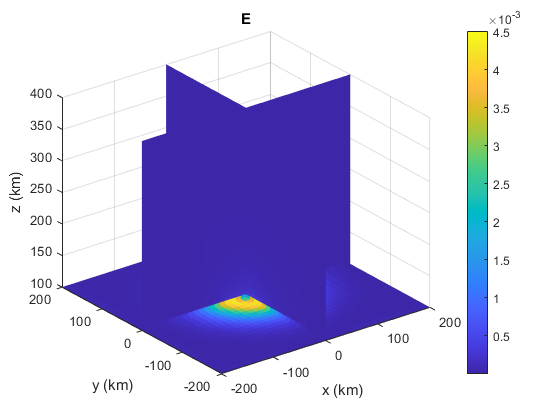

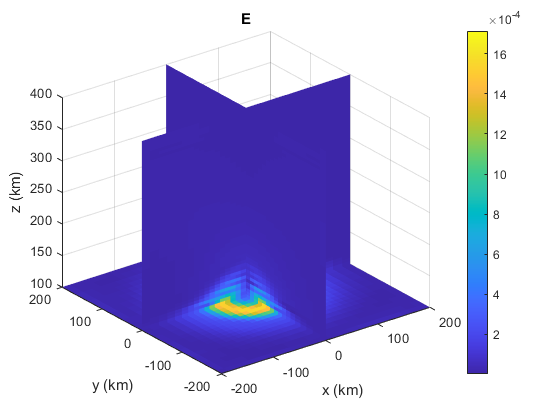

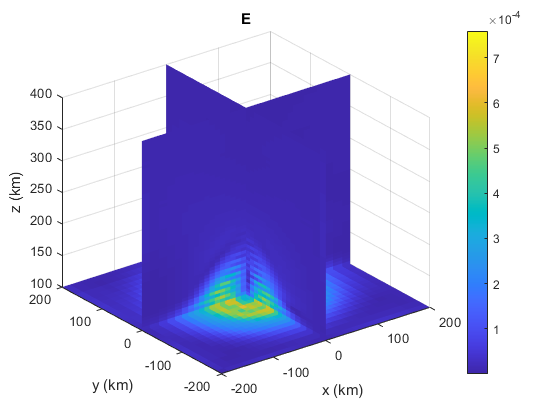

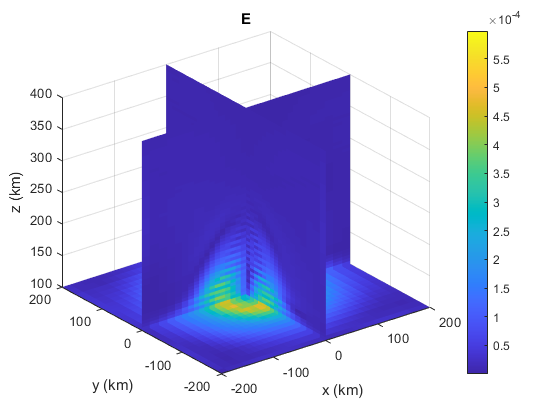

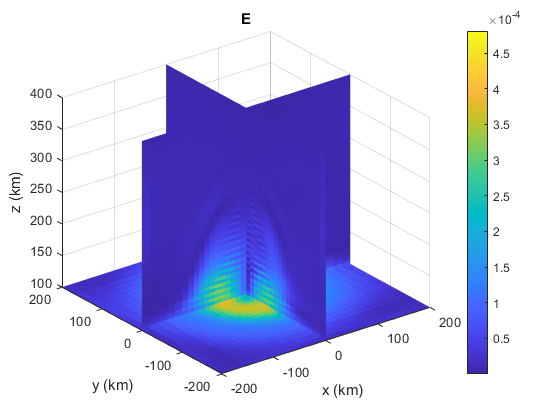

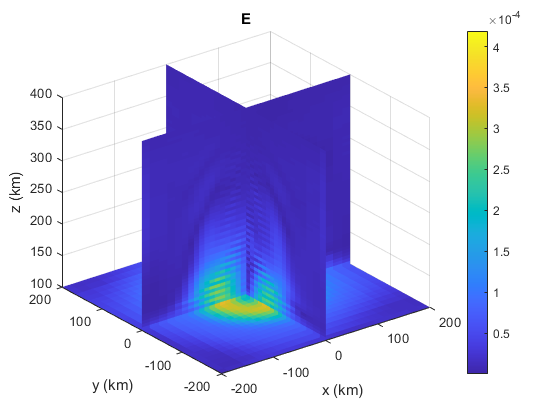

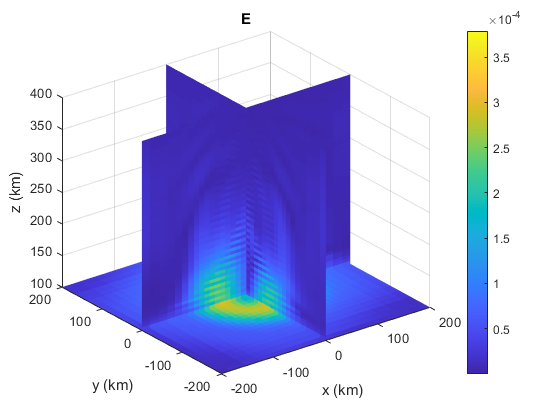

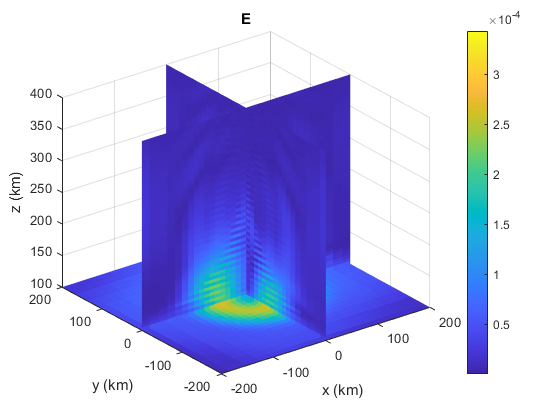

ShowEq   = 0;
species  = ["nO2p","nOp","nCO2p"];

ShowProf = 0;
ShowB    = 0;
ShowE    = 1;
ShowJ    = 0;

si_BEJ   = 12; % Temporal slice index for B, E, and J field plots

if (ShowEq==1)
    Zidx = 15;
    Check_Equilibrium(Zidx,species,t,Z,dataTable,n0);
end

if (ShowProf==1)
    Density_Animation(save_name, dataTable, t, n0, mx, my, Z);
end

if (ShowB==1)
    name = 'B';
    norm = B0;
    Plot_Vector_Field(dataTable,X,Y,Z,name,norm,si_BEJ);
end
if (ShowE==1)
    name = 'E';
    norm = E0;
    %Plot_Vector_Field(dataTable,X,Y,Z,name,norm,si_BEJ);
    Vector_Field_Animation(save_name,dataTable,X,Y,Z,name,norm)
end

if (ShowJ==1)
    name = 'J';
    norm = J0;
    %Plot_Vector_Field(dataTable,X,Y,Z,name,norm,si_BEJ);
    Vector_Field_Animation(save_name,dataTable,X,Y,Z,name,norm)
end

% Attempt to reproduce Riousset 2013 Fig 4b
%{
figure;
sx = dataTable{si_BEJ,'Ex'}{1}.*E0;
sy = dataTable{si_BEJ,'Ey'}{1}.*E0;
sz = dataTable{si_BEJ,'Ez'}{1}.*E0;
mag = sqrt(sx.^2+sy.^2+sz.^2);

Xdata = slice(X,Y,Z,mag,[0], [0], [130]);
set(Xdata,'EdgeColor','none','FaceColor','interp','FaceAlpha','interp');
alpha('color');
alphamap('rampdown')
alphamap('increase',.1)
colormap jet
colorbar;
axis equal;
title('|E|');
xlabel("x (km)");
ylabel("y (km)");
zlabel("z (km)");
xlim([-100,100]);
ylim([-50,50]);
view(10,10);
%}


fclose('all');
cd(root_path);

function Density_Animation(save_name, dataTable, t, n0, mx, my, Z)
    global root_path
    cd(root_path);
    if ~exist('viz_dir', 'dir')
       mkdir('viz_dir');
    end
    cd 'viz_dir/';
    
    AnimationTime = 5;
    n_steps = height(dataTable);
    
    v = VideoWriter(strcat('density_',save_name));
    v.FrameRate = n_steps/AnimationTime;
    open(v);
    
    h = figure;
    h.Color = 'white';
    h.Visible = 'off';
    M(n_steps-1) = struct('cdata',[],'colormap',[]);
    for i=1:n_steps
        nOp   = dataTable{i,"nOp"}{1}.*(n0/10^6);
        nO2p  = dataTable{i,"nO2p"}{1}.*(n0/10^6);
        nCO2p = dataTable{i,"nCO2p"}{1}.*(n0/10^6);
        ne    = nOp + nO2p + nCO2p;
        
        nOpz   = squeeze(nOp(floor(mx/2),floor(my/2),:))';
        nO2pz  = squeeze(nO2p(floor(mx/2),floor(my/2),:))';
        nCO2pz = squeeze(nCO2p(floor(mx/2),floor(my/2),:))';
        nez    = squeeze(ne(floor(mx/2),floor(my/2),:))';

        semilogx(nez,   Z,'DisplayName','e^-',   'LineWidth',1,'Color','m','LineStyle','-');
        hold on;
        semilogx(nCO2pz,Z,'DisplayName','CO_2^+','LineWidth',1,'Color','r','LineStyle','--');
        semilogx(nO2pz, Z,'DisplayName','O_2^+', 'LineWidth',1,'Color','k','LineStyle','-.');
        semilogx(nOpz,  Z,'DisplayName','O^+',   'LineWidth',1,'Color','b','LineStyle',':');
        
        
        %%%%%%CHECK WITH THEORETICAL%%%%%%%%
        
        tempCO2 = [107.28443014544911, 238.81087784813934,186.81809528372952, 231.66782071435557,234.7542544916016, 228.73721448609507,314.6875438309644, 224.59740261321213,395.03062258963615, 221.05560394575534,464.5663141383297, 218.36082281080465,583.1088976231371, 214.75111387232602,706.8980779994838, 210.28593692918963,888.1486408313958, 207.26478367290005,1115.366197275364, 203.97198933252324,1355.6298531130644, 201.0461118658813,1647.6492681422417, 198.12023439923934,1936.9460712938242, 195.19908569421594,2202.083207554452, 192.19211872278197,4713.658420891596, 175.60064559651647,5408.092713513752, 171.41499100683157,5952.282040476774, 168.95603496519067,8496.361932707108, 162.52045311133625,9975.335409790083, 158.82965466806564,12094.845277034583, 154.45502475295834,23717.072856163344, 138.60053788190828,24352.137742153875, 134.46686464216347,24228.71247608603, 131.42448450038623,21823.663513818727, 128.6950958359606,16631.980222543043, 125.6769637329273,11868.059507423008, 123.16629780729107,7924.805887082224, 120.82354670394281,5296.532173844187, 119.02407776876905,3542.6070491965934, 117.67734397374073,2368.7705537823995, 116.14951612265423,1582.9248605572204, 114.25950015945139];
        j = 1;
        while j <= length(tempCO2)-1
            tempCO2x(ceil(j/2)) = tempCO2(j);
            tempCO2y(ceil(j/2)) = tempCO2(j+1);
            j = j+2;
        end
        tempO2 = [30716.31948711234, 113.83864037540133,47152.29831133881, 115.02766121348537,68868.39878425805, 118.34304852603967,90537.83835885575, 122.50056406510558,101597.60708683495, 124.98993596851514,101130.9232323651, 128.88503442763863,89302.21869106576, 134.22811472222295,81336.75599658009, 138.15393261793503,73250.23190306373, 141.97267033388505,63079.59146276196, 145.59398225226101,55546.61432835882, 149.26948811397637,50646.90116378556, 153.84422637723023,41837.88091825807, 159.1696000866429,37986.97917918481, 161.22109450215294,32362.254713340222, 165.0477134874672,27139.47268453116, 169.41997902176522,22749.762040949743, 173.53418552618035,20721.028505316535, 177.4735854760968,17636.859602341927, 180.75692229323653,15534.459851840646, 184.57881251693226,13708.773140758605, 189.54159529379444,9703.790463509347, 202.17059386483822,6779.688133550657, 206.9763292141691,5580.6283729526585, 210.1738477648983,4758.261881010145, 214.49847540437253,4190.103243889844, 218.18454508602463,3456.6103834335577, 222.69499554317554,2752.6528624501793, 226.0330633975669,2268.559894104719, 229.9549581725288,1998.7409193875378, 233.95794245228268,1645.9889733005732, 237.42710208709912];
        j = 1;
        while j <= length(tempO2)-1
            tempO2x(ceil(j/2)) = tempO2(j);
            tempO2y(ceil(j/2)) = tempO2(j+1);
            j = j+2;
        end
        tempO = [0.7937273274502612, 114.7491021262895,1.2100019186430861, 115.76702936344202,1.737870386168309, 117.01983594158062,2.64942610966869, 118.06492728714184,3.95994441352583, 119.23056702611197,5.921386363699842, 120.66784784916939,8.85771906416737, 122.33149624229952,13.24312670265674, 123.67823003732786,19.817699092943634, 125.56824600053068,29.678661595817765, 127.91099710387894,43.001413018341694, 130.4214616192981,60.30030820122635, 133.30789771125504,79.17156352437125, 136.69274527780613,94.01334775449823, 139.79297393671683,108.07692789910513, 143.4412135254206,120.14537647205104, 146.95836133369926,133.53115884527594, 150.33968859993433,145.9623927163447, 157.0744084109912,138.62657488932382, 152.8068937035098,155.82177194156677, 162.95208396351745,167.84926762636397, 167.5605248697637,174.40449980667086, 170.54384803310495,187.35565564568742, 173.52244243482767,208.79714372426574, 178.5336162055862,228.3734529267478, 185.63052412875942,217.09925658178955, 181.92440099505836,259.67559788477456, 189.37088699936515,289.21857173008755, 194.01987265800736,355.26075127163136, 197.43228715340135,436.38346126634383, 200.8447016487953,501.7764469216845, 204.6287617795427,570.8816677876953, 210.04455991946105,606.6152466081313, 218.45881325989996,602.2278199242932, 214.11255591450387,675.4503379316304, 222.9493416194913,805.1412358876071, 228.3358827361364,925.7933548660269, 232.11994286688378,1100.3438459377821, 235.76345369396898,1305.7293536175819, 238.45622072674882];
        j = 1;
        while j <= length(tempO)-1
            tempOx(ceil(j/2)) = tempO(j);
            tempOy(ceil(j/2)) = tempO(j+1);
            j = j+2;
        end
        semilogx(tempOx,tempOy,'.','DisplayName','O^+ theo','Color','b');
        semilogx(tempO2x,tempO2y,'.','DisplayName','O_2^+ theo','Color','k');
        semilogx(tempCO2x,tempCO2y,'.','DisplayName','CO_2^+ theo','Color','r');
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        
        hold off;
        legend('show','Location','east');
        legend boxoff;
        title(['n_s at t = ',num2str(t(i+1),'%06.2f'),'s']);
        xlabel("n_s (cm^-^3)");
        ylabel("z (km)");
        xlim([10^0,10^7]);
        ylim([100 400]);
        drawnow;
        
        M(i) = getframe(gcf);
        writeVideo(v,M(i));
    end
    h.Visible = 'on';
    movie(gcf,M,1,n_steps/AnimationTime);
    close(v);
end

function t = Add_data_to_table(t, file_n, in_args)
    nbvarsX = in_args{1};
    nbvarsY = in_args{2};
    mx      = in_args{3};
    my      = in_args{4};
    mz      = in_args{5};
    tNew    = in_args{6};
    nbvars  = nbvarsX+nbvarsY;
    
    X_name = ['X',num2str(file_n),'.bin'];
    Y_name = ['Y',num2str(file_n),'.bin'];
    
    file_data = PetscOpenFile(X_name);
    Xdata = PetscBinaryRead(file_data);
    Xdata = reshape(Xdata,nbvarsX,mx,my,mz);
    close(file_data);
    
    if (nbvarsY > 0)
        file_data = PetscOpenFile(Y_name);
        Ydata = PetscBinaryRead(file_data);
        Ydata = reshape(Ydata,nbvarsY,mx,my,mz);
        close(file_data);
    end
    
    for i = 1:nbvars
        if (i <= nbvarsX)
           tNew{1,i}{1} = permute(squeeze(Xdata(i,:,:,:)),[2 1 3]);
        else
           tNew{1,i}{1} = permute(squeeze(Ydata(i-nbvarsX,:,:,:)),[2 1 3]);
        end
        
        tNew.Properties.RowNames{1} = num2str(file_n);
        if (nbvarsY == 0)
            tNew.Properties.RowNames{1} = append('X',tNew.Properties.RowNames{1});
        end
    end
    
    if (isempty(t{1,1}{1}))
        t = tNew;
    else
        t = [t;tNew];
    end
end

function t = Get_times(t_Name, numInputFiles)
    fid = fopen(t_Name,'r');
    if fid == -1
        disp("File "+t_Name+" doesn't currently exist in "+pwd);
        return;
    end
    
    t = zeros(1,numInputFiles);
    i = 1;
    while i<=numInputFiles
        t(i) = str2double(fgetl(fid));
        
        if (i==1 && not(t(i)==0))   % Sometimes (for some reason) t.out doesn't include the 0th time step, this manually adds it if it isn't there.
            i = i+1;
            t(2) = t(1);
            t(1) = 0;
        end
        
        i = i+1;
    end
    fclose(fid);
end

function x = Generate_Axis(out_min,in_min,in_max,out_max,mx_in,pct)
    L = 1000; % m/km

    Lx = in_max-in_min;
    dx = Lx/(mx_in-1);
    mx_lo = ceil( log((pct-1)*(in_min - out_min)/(pct*dx) + 1)/log(pct));
    mx_hi = floor(log((pct-1)*(out_max - in_max)/(pct*dx) + 1)/log(pct));
    
    X = in_min - pct*dx * (pct^mx_lo-1) / (pct-1);
    if (X > out_min)
        mx_lo = mx_lo+1;
    end
    
    X = in_max + pct*dx * (pct^mx_hi-1) / (pct-1);
    if (X < out_max)
        mx_hi = mx_hi+1;
    end
    
    mx = mx_lo + mx_in + mx_hi;
    x = zeros(1,mx);
    
    for i = 0:mx-1
        if (i < mx_lo)
            X = in_min - pct*dx*(pct^(mx_lo-i) - 1) / (pct-1);
        elseif (i >= mx_lo && i < mx_lo+mx_in)
            X = in_min + (i-mx_lo)*dx;
        else
            X = in_max + pct*dx*(pct^(i-mx_lo-mx_in+1) - 1) / (pct-1);
        end
        x(i+1) = X/L;
    end
end

function tline = Get_Parameter(fName, str)
    str = strrep(str,' ','');
    
    fid = fopen(fName,'r');
    if fid == -1
        disp("File "+fName+" doesn't currently exist in "+pwd);
        return;
    end

    tline = fgetl(fid);
    while ischar(tline)
        if (strcmp(fName, 'out.txt'))
                tline = strrep(tline,' ','');
        end
        
        if (contains(tline, str) && not(tline(1) == "#"))
            temp = textscan(tline,[str,'%f']);
            if (temp{1})
                tline = temp{1};
            else
                a = split(tline);
                if (length(a)>1)
                    a = a(2);
                end
                if (strcmp(str,'input_file'))
                    a = textscan(a{1},'X%f.bin');
                else
                    a = textscan(a{1},'%f');
                end
                tline = a{1};
            end
            return;
        end
        tline = fgetl(fid);
    end
    tline = "no pattern found";
    disp(tline);
    fclose(fid);
end

function Print_useful_IC_info(input_name)
    disp('Simulation parameters:');
    bc_type      = Get_Parameter(input_name, 'bc_type');
    WindNS       = Get_Parameter(input_name, 'WindNS');
    WindEW       = Get_Parameter(input_name, 'WindEW');
    WindUD       = Get_Parameter(input_name, 'WindUD');
    iWindNS      = Get_Parameter(input_name, 'iWindNS');
    iWindEW      = Get_Parameter(input_name, 'iWindEW');
    iWindUD      = Get_Parameter(input_name, 'iWindUD');
    B_field_type = Get_Parameter(input_name, 'B_field_type');
    B0           = Get_Parameter(input_name, 'B0');
    Chemistry    = Get_Parameter(input_name, 'chem_switch');
    Collisions   = Get_Parameter(input_name, 'coll_switch');
    Gradp        = Get_Parameter(input_name, 'gradp_switch');
    Gravity      = Get_Parameter(input_name, 'grav_switch');
    
    
    switch bc_type
        case 0
            disp('  BC type:        1st order Neumann');
        case 1
            disp('  BC type:        2nd order Neumann');
        case 2
            disp("  BC type:        zero'd 2nd derivatives");
        case 3
            disp('  BC type:        Non-symettric "exact" solution');
        case 10
            disp('  BC type:        combination of df/dn=0 and d2f/dn2=0'); 
    end
    
    if (abs(WindNS)+abs(WindEW)+abs(WindUD) > 0)
        if not(WindNS == 0)
            if WindNS > 0
                disp(['  South Nwind:    ',num2str(abs(WindNS)),' m/s']);
            else
                disp(['  North Nwind:    ',num2str(abs(WindNS)),' m/s']);
            end
        end
        if not(WindEW == 0)
            if WindEW > 0
                disp(['  West Nwind:     ',num2str(abs(WindEW)),' m/s']);
            else
                disp(['  East Nwind:     ',num2str(abs(WindEW)),' m/s']);
            end
        end
        if not(WindUD == 0)
            if WindUD > 0
                disp(['  Down Nwind:     ',num2str(abs(WindUD)),' m/s']);
            else
                disp(['  Upward Nwind:   ',num2str(abs(WindUD)),' m/s']);
            end
        end
    else
        disp('  Neutral Wind:   None');
    end
    
    if (abs(iWindNS)+abs(iWindEW)+abs(iWindUD) > 0)
        if not(iWindNS == 0)
            if iWindNS > 0
                disp(['  South Iwind:    ',num2str(abs(iWindNS)),' m/s']);
            else
                disp(['  North Iwind:    ',num2str(abs(iWindNS)),' m/s']);
            end
        end
        if not(iWindEW == 0)
            if iWindEW > 0
                disp(['  West Iwind:     ',num2str(abs(iWindEW)),' m/s']);
            else
                disp(['  East Iwind:     ',num2str(abs(iWindEW)),' m/s']);
            end
        end
        if not(iWindUD == 0)
            if iWindUD > 0
                disp(['  Down Iwind:     ',num2str(abs(iWindUD)),' m/s']);
            else
                disp(['  Upward Iwind:   ',num2str(abs(iWindUD)),' m/s']);
            end
        end
    else
        disp('  Ion Wind:       None');
    end
    
    switch B_field_type
        case 0
            disp('  B field type:   Measured');
        case 1
            disp('  B field type:   Uniform vertical');
        case 2
            disp('  B field type:   Uniform horizontal');
        case 3
            disp('  B field type:   Dipole verticle');
        case 4
            disp('  B field type:   Dipole horizontal');
        case 5
            disp('  B field type:   Uniform then erf decreasing vertical');
        case 6
            disp('  B field type:   Uniform then z^-3 decreasing vertical');
        case 7
            disp('  B field type:   Arcades');
        case 8
            disp('  B field type:   Three lines of dipoles giving parallel arcades');
        case 9
            disp('  B field type:   Read from input binary file');
    end
    
    fprintf('  B field mag:    %s\n', num2str(B0));
    
    switch Chemistry
        case 0
            disp('  Chemistry:      OFF');
        case 1
            disp('  Chemistry:      ON');
    end
    
    switch Collisions
        case 0
            disp('  Collisions:     OFF');
        case 1
            disp('  Collisions:     ON');
    end
    
    switch Gradp
        case 0
            disp('  Pressure Grad:  OFF');
        case 1
            disp('  Pressure Grad:  ON');
    end
    
    switch Gravity
        case 0
            disp('  Gravity:        OFF');
        case 1
            disp('  Gravity:        ON');
    end
end

function Vector_Field_Animation(save_name, dataTable, X, Y, Z, s, norm)
    global root_path
    cd(root_path);
    if ~exist('viz_dir', 'dir')
       mkdir('viz_dir');
    end
    cd 'viz_dir/';
    
    AnimationTime = 5;
    n_steps = height(dataTable);
    v = VideoWriter(strcat('field_',s,'_',save_name));
    v.FrameRate = n_steps/AnimationTime;
    open(v);
    
    h = figure;
    h.Color = 'white';
    h.Visible = 'off';
    M(n_steps-1) = struct('cdata',[],'colormap',[]);
    for i=1:n_steps
        Plot_Vector_Field(dataTable,X,Y,Z,s,norm,i)
        drawnow;
        M(i) = getframe(gcf);
        writeVideo(v,M(i));
    end
    h.Visible = 'on';
    movie(gcf,M,1,n_steps/AnimationTime);
    close(v);
end

function Plot_Vector_Field(dataTable,X,Y,Z,s,norm,slicei)
    figure;

    name_x = s+"x";
    name_y = s+"y";
    name_z = s+"z";
    sx = dataTable{slicei,name_x}{1}.*norm;
    sy = dataTable{slicei,name_y}{1}.*norm;
    sz = dataTable{slicei,name_z}{1}.*norm;
    
    if (s == 'B')
        mag = sz;
    else
        mag = sqrt(sx.^2+sy.^2+sz.^2); 
    end
    
    xslices = [0];
    yslices = [0];
    zslices = [100];
    
    if (s=='B')
        xslices = [];
        yslices = [];
    end
    
    Xdata = slice(X,Y,Z,mag,xslices,yslices,zslices);
    set(Xdata, 'EdgeColor', 'none');
    hold on;
    [Sy,Sz,Sx] = meshgrid(-50:20:50,110,-50:20:50);
    if (s=='B')
        streamline(stream3(X,Y,Z,sx,sy,sz,Sx,Sy,Sz));
    end
    title(s);
    xlabel("x (km)");
    ylabel("y (km)");
    zlabel("z (km)");
    xlim([-200,200]);
    ylim([-200 200]);
    zlim([100 400]);
    colorbar;
    %caxis([0 1e-2]);
end

function Check_Equilibrium(Zidx,species,t,Z,dataTable,n0)
    Xidx = 18;
    Yidx = 18;
    ns = length(species);
    n = zeros(ns,height(dataTable));
    for i=1:height(dataTable)
        for j=1:ns
            n_all = dataTable{i,species(j)}{1};
            n(j,i) = n_all(Xidx,Yidx,Zidx)*(n0/10^6);
        end
    end
    
    dn = zeros(ns,height(dataTable));
    for i=1:ns
        dn(i,:) = n(i,:)-n(i,1);
    end
    
    figure;
    colors = ['b','r','m'];
    
    plot(t,zeros(1,length(t)),'LineWidth',2,'Color','#008000');
    hold on;
    for i=1:ns
        plot(t,dn(i,:),'LineWidth',2,'Color',colors(i));
    end
    
    if (ns==2)
        dn2_flip = -dn(2,:);
        plot(t,dn2_flip,'LineWidth',2,'LineStyle','--','Color','#FFA500');
    end
    
    T = title("Altitude z = "+Z(Zidx));
    for i=ns:-1:1
        origtitle = get(T,'String');
        set(T,'String',species(i)+' '+origtitle);
        
    end
    
    if (ns==3)
        legend("y=0",species(1),species(2),species(3),'Location','northwest');
    else
        legend("y=0",species(1),species(2),'-('+species(2)+')','Location','northwest');
    end
    
    legend boxoff;
    grid on;
    xlabel("time (s)");
    ylabel("\Deltan cm^-^3");
    hold off;
end